## Single-Sample NTN Channel & Doppler Pre-compensation Demo

Y = X .* H 

No adding noise to see the Doppler effect

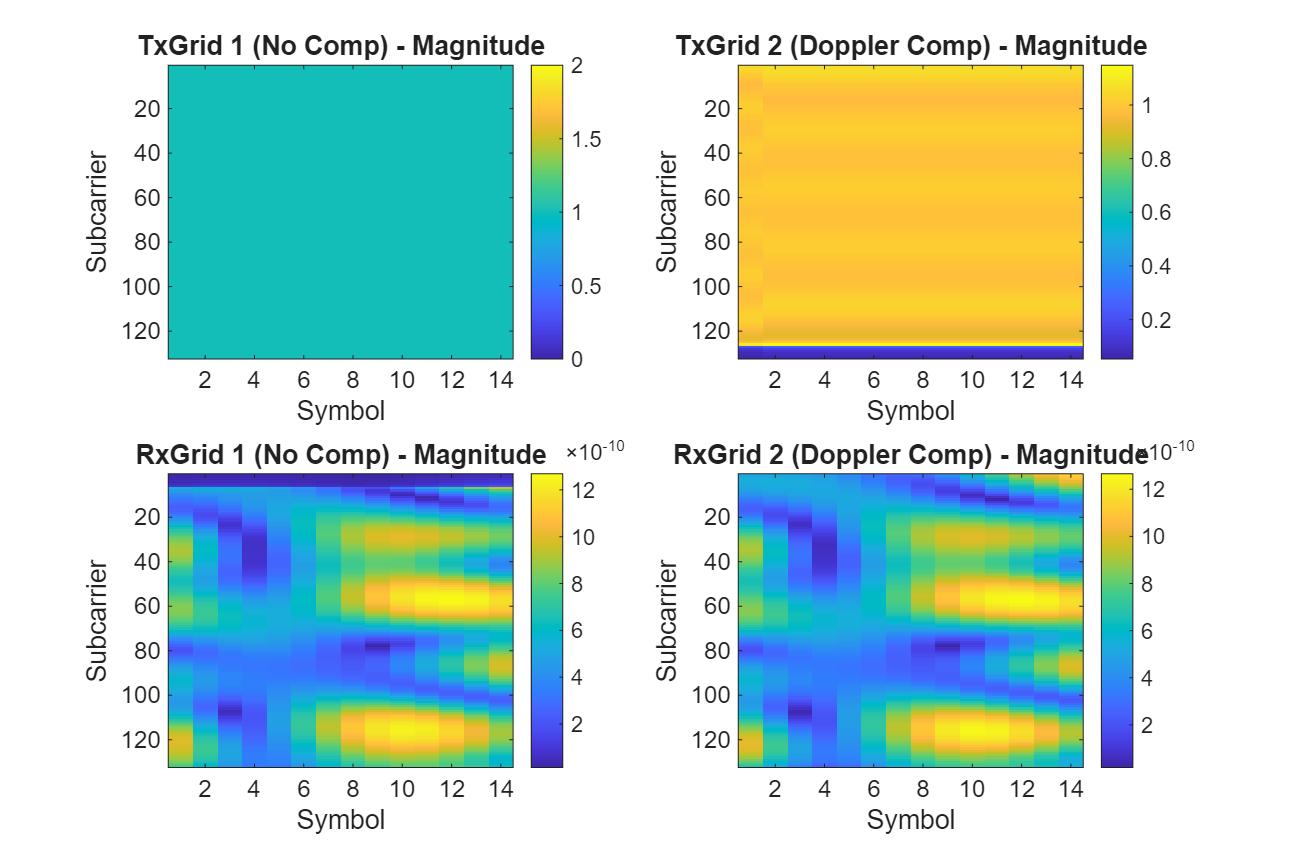

%% Single-Sample NTN Channel & Doppler Pre-compensation Demo
% This script models a single transmission sample (1 all-ones txGrid, 1 channel realization, 1 rxGrid)
% without noise for two cases:
%   Version 1: No Doppler pre-compensation (Original NTN Channel)
%   Version 2: Sample-wise Doppler pre-compensation on txWaveform (Effective NTN Channel)

clear; clc; close all;

% Set up script path and helper path
try
    script_dir = fileparts(matlab.desktop.editor.getActiveFilename);
catch
    script_dir = '';
end
if isempty(script_dir) || ~exist(script_dir, 'dir')
    script_dir = fileparts(mfilename('fullpath'));
end
if isempty(script_dir) || ~exist(script_dir, 'dir')
    script_dir = pwd;
end
cd(script_dir);
addpath('..\helper\');

%% 1. Simulation & Channel Configuration
simParameters.CarrierFrequency = 27e9;       % 27 GHz Carrier frequency
simParameters.SatelliteAltitude = 1000000;   % 1000 km Satellite altitude
simParameters.ElevationAngle = 50;           % 50 degrees Elevation angle
simParameters.MobileSpeed = 30;              % 30 m/s Mobile terminal speed
simParameters.MobileAltitude = 0;

carrier = nrCarrierConfig;
carrier.NSizeGrid = 11;                      % 11 Resource Blocks (132 subcarriers)
carrier.SubcarrierSpacing = 60;              % 60 kHz SCS
carrier.CyclicPrefix = 'Normal';

waveformInfo = nrOFDMInfo(carrier);
simParameters.SampleRate = waveformInfo.SampleRate;
c = physconst("lightspeed");

satelliteDopplerShift = dopplerShiftCircularOrbit( ...
    simParameters.ElevationAngle, simParameters.SatelliteAltitude, ...
    simParameters.MobileAltitude, simParameters.CarrierFrequency);

nTxAnts = 1;
nRxAnts = 1;

channel = nrTDLChannel;
channel.DelayProfile = 'NTN-TDL-A';
channel.DelaySpread = 200e-9;
channel.SatelliteDopplerShift = satelliteDopplerShift;
channel.MaximumDopplerShift = simParameters.MobileSpeed * simParameters.CarrierFrequency / c;
channel.NumTransmitAntennas = nTxAnts;
channel.NumReceiveAntennas = nRxAnts;
channel.SampleRate = waveformInfo.SampleRate;
channel.RandomStream = "mt19937ar with seed";
channel.Seed = 42; % Fixed seed for reproducible single sample

simParameters.IncludeFreeSpacePathLoss = true;
tmpInfo = HelperNRNTNThroughput.initializeDelayObjects_simplified(simParameters);
pl_dB = tmpInfo.pathLoss; % Path loss in dB

chInfo = info(channel);
maxChDelay = ceil(max(chInfo.PathDelays * channel.SampleRate)) + chInfo.ChannelFilterDelay;

%% 2. Version 1: No Doppler Compensation
% 2.1 Transmit Grid & Waveform (All-ones grid)
txGrid1 = ones(carrier.NSizeGrid * 12, carrier.SymbolsPerSlot); % 132 x 14 grid of ones
[txWaveform1, ~] = nrOFDMModulate(carrier, txGrid1);
txWaveform1_padded = [txWaveform1; zeros(maxChDelay, size(txWaveform1, 2))];

% 2.2 Pass through Channel
reset(channel);
channel.Seed = 42;
[rxWaveform1, pathGains1] = channel(txWaveform1_padded);

% 2.3 Receiver Demodulation & Perfect Channel Estimation
pathFilters1 = getPathFilters(channel);
offset1 = nrPerfectTimingEstimate(pathGains1, pathFilters1);
rxGrid1_raw = nrOFDMDemodulate(carrier, rxWaveform1(1+offset1:end, :));
rxGrid1 = rxGrid1_raw * db2mag(-pl_dB); % Original received grid (uncompensated channel)

hEst1_raw = nrPerfectChannelEstimate(carrier, pathGains1, pathFilters1, offset1);
H_perfect_ori = hEst1_raw * db2mag(-pl_dB); % 132 x 14 original channel

%% 3. Version 2: With Sample-Wise Doppler Pre-Compensation
% 3.1 Sample-wise Doppler Pre-compensation on Tx Waveform
t = (0:size(txWaveform1_padded, 1) - 1)' / simParameters.SampleRate;
txWaveform2_padded = txWaveform1_padded .* exp(1j * 2 * pi * (-satelliteDopplerShift) * t);
txWaveform2 = txWaveform2_padded(1:size(txWaveform1, 1), :);

% Demodulate txWaveform2 to see the pre-compensated Tx grid
txGrid2 = nrOFDMDemodulate(carrier, txWaveform2);

% 3.2 Pass through Channel (using identical channel realization seed)
release(channel);
channel.Seed = 42;
[rxWaveform2, pathGains2] = channel(txWaveform2_padded);

% 3.3 Receiver Demodulation & Effective Channel Estimation
pathFilters2 = getPathFilters(channel);
offset2 = nrPerfectTimingEstimate(pathGains2, pathFilters2);
rxGrid2_raw = nrOFDMDemodulate(carrier, rxWaveform2(1+offset2:end, :));
rxGrid2 = rxGrid2_raw * db2mag(-pl_dB); % Effective received grid (Doppler pre-compensated)

hEst2_raw = nrPerfectChannelEstimate(carrier, pathGains2, pathFilters2, offset2);
H_perfect_eff = rxGrid2; % Effective channel matrix

%% 4. Plotting Resource Grids (Magnitude & Phase)
% 4.1 Magnitude of Resource Grids
figure('Name', 'Resource Grids Magnitude', 'Position', [100, 100, 1200, 800]);
subplot(2,2,1);
imagesc(abs(txGrid1)); colorbar; set(gca, 'FontSize', 12);
title('TxGrid 1 (No Comp) - Magnitude'); xlabel('Symbol'); ylabel('Subcarrier');

subplot(2,2,2);
imagesc(abs(txGrid2)); colorbar; set(gca, 'FontSize', 12);
title('TxGrid 2 (Doppler Comp) - Magnitude'); xlabel('Symbol'); ylabel('Subcarrier');

subplot(2,2,3);
imagesc(abs(rxGrid1)); colorbar; set(gca, 'FontSize', 12);
title('RxGrid 1 (No Comp) - Magnitude'); xlabel('Symbol'); ylabel('Subcarrier');

subplot(2,2,4);
imagesc(abs(rxGrid2)); colorbar; set(gca, 'FontSize', 12);
title('RxGrid 2 (Doppler Comp) - Magnitude'); xlabel('Symbol'); ylabel('Subcarrier');

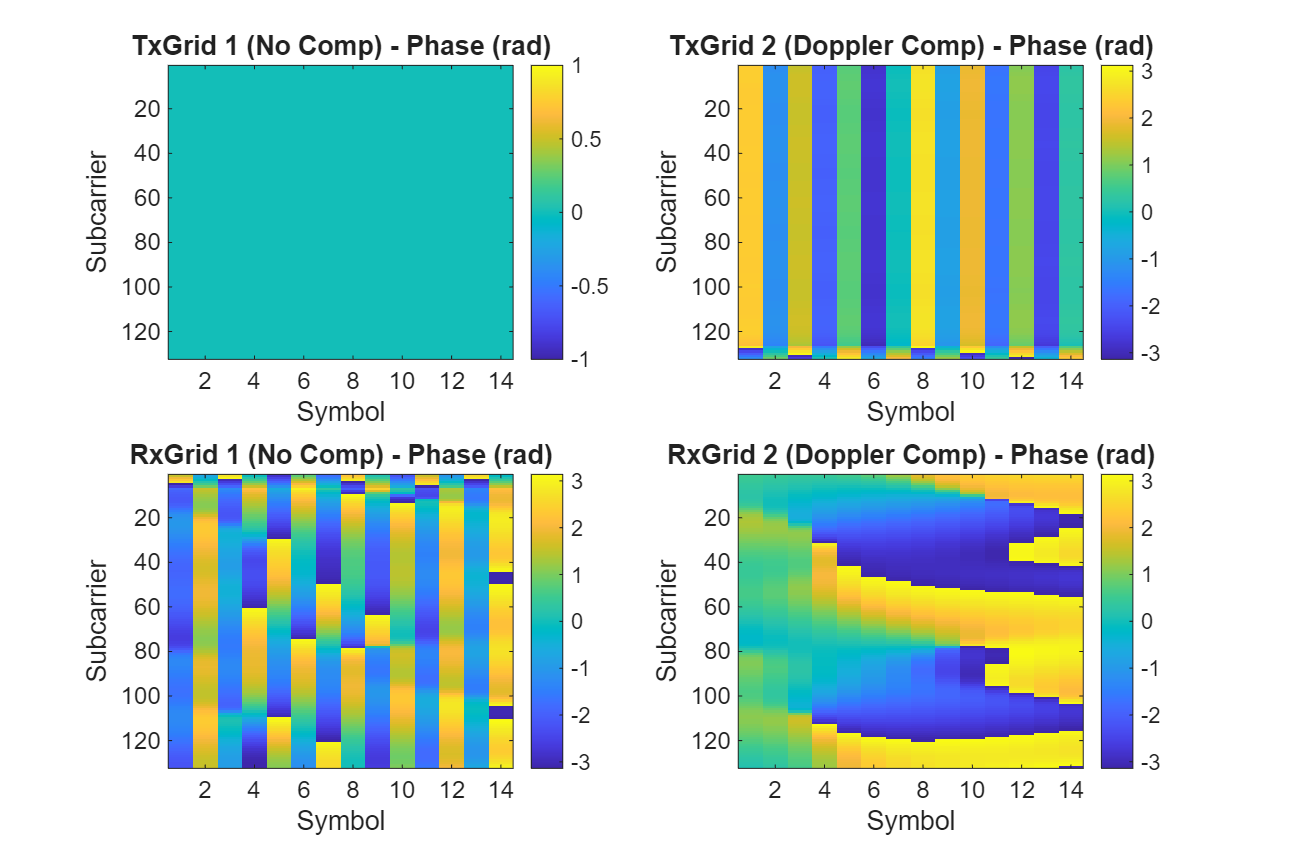


% 4.2 Phase of Resource Grids
figure('Name', 'Resource Grids Phase', 'Position', [150, 150, 1200, 800]);
subplot(2,2,1);
imagesc(angle(txGrid1)); colorbar; set(gca, 'FontSize', 12);
title('TxGrid 1 (No Comp) - Phase (rad)'); xlabel('Symbol'); ylabel('Subcarrier');

subplot(2,2,2);
imagesc(angle(txGrid2)); colorbar; set(gca, 'FontSize', 12);
title('TxGrid 2 (Doppler Comp) - Phase (rad)'); xlabel('Symbol'); ylabel('Subcarrier');

subplot(2,2,3);
imagesc(angle(rxGrid1)); colorbar; set(gca, 'FontSize', 12);
title('RxGrid 1 (No Comp) - Phase (rad)'); xlabel('Symbol'); ylabel('Subcarrier');

subplot(2,2,4);
imagesc(angle(rxGrid2)); colorbar; set(gca, 'FontSize', 12);
title('RxGrid 2 (Doppler Comp) - Phase (rad)'); xlabel('Symbol'); ylabel('Subcarrier');

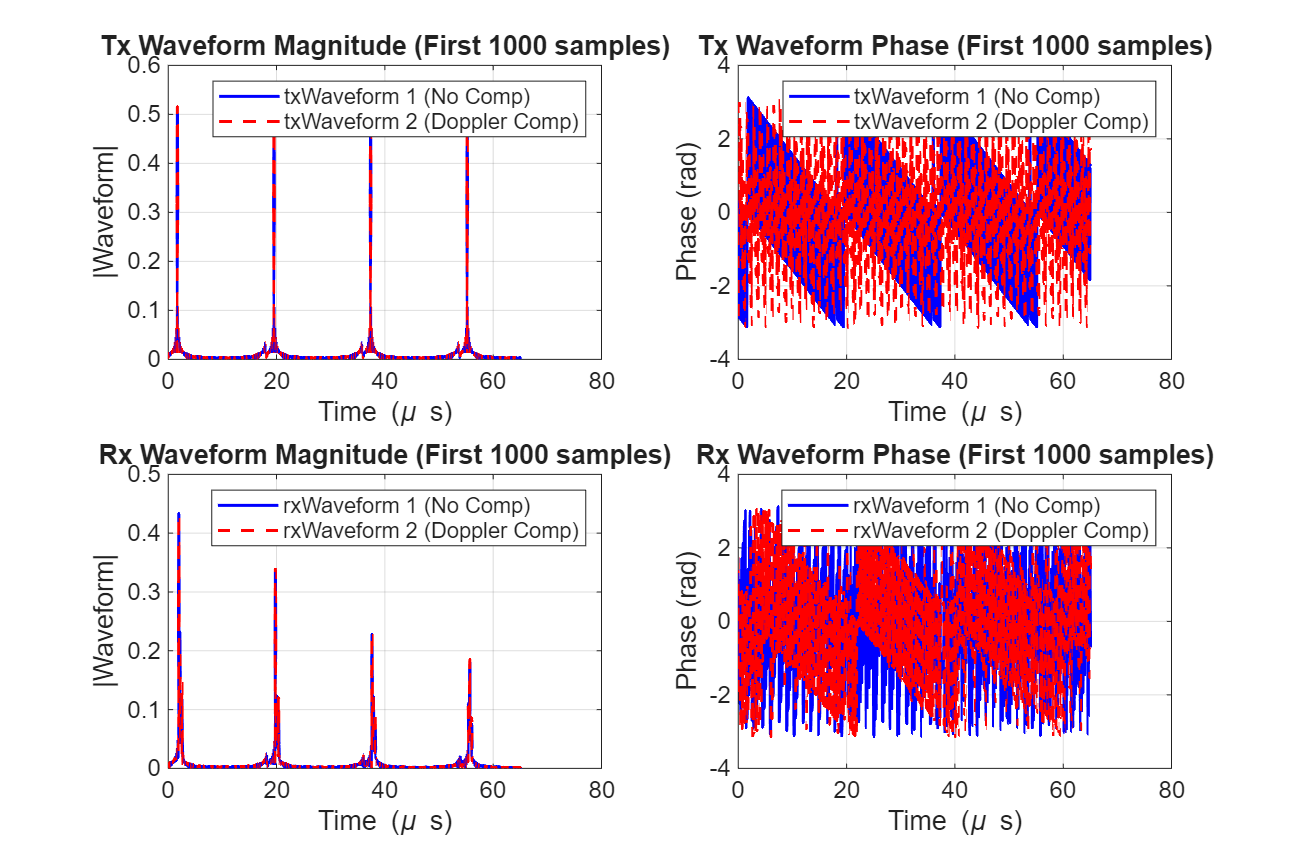

%% 5. Plotting Time-Domain Waveforms (Magnitude & Phase)
t_us = t * 1e6; % time in microseconds

figure('Name', 'Time-Domain Waveforms - Tx & Rx', 'Position', [250, 250, 1200, 800]);
subplot(2,2,1);
plot(t_us(1:1000), abs(txWaveform1_padded(1:1000)), 'b', 'LineWidth', 1.5); hold on;
plot(t_us(1:1000), abs(txWaveform2_padded(1:1000)), 'r--', 'LineWidth', 1.5); hold off;
grid on; set(gca, 'FontSize', 12);
title('Tx Waveform Magnitude (First 1000 samples)'); xlabel('Time (\mu s)'); ylabel('|Waveform|');
legend('txWaveform 1 (No Comp)', 'txWaveform 2 (Doppler Comp)');

subplot(2,2,2);
plot(t_us(1:1000), angle(txWaveform1_padded(1:1000)), 'b', 'LineWidth', 1.5); hold on;
plot(t_us(1:1000), angle(txWaveform2_padded(1:1000)), 'r--', 'LineWidth', 1.5); hold off;
grid on; set(gca, 'FontSize', 12);
title('Tx Waveform Phase (First 1000 samples)'); xlabel('Time (\mu s)'); ylabel('Phase (rad)');
legend('txWaveform 1 (No Comp)', 'txWaveform 2 (Doppler Comp)');

subplot(2,2,3);
plot(t_us(1:1000), abs(rxWaveform1(1:1000)), 'b', 'LineWidth', 1.5); hold on;
plot(t_us(1:1000), abs(rxWaveform2(1:1000)), 'r--', 'LineWidth', 1.5); hold off;
grid on; set(gca, 'FontSize', 12);
title('Rx Waveform Magnitude (First 1000 samples)'); xlabel('Time (\mu s)'); ylabel('|Waveform|');
legend('rxWaveform 1 (No Comp)', 'rxWaveform 2 (Doppler Comp)');

subplot(2,2,4);
plot(t_us(1:1000), angle(rxWaveform1(1:1000)), 'b', 'LineWidth', 1.5); hold on;
plot(t_us(1:1000), angle(rxWaveform2(1:1000)), 'r--', 'LineWidth', 1.5); hold off;
grid on; set(gca, 'FontSize', 12);
title('Rx Waveform Phase (First 1000 samples)'); xlabel('Time (\mu s)'); ylabel('Phase (rad)');
legend('rxWaveform 1 (No Comp)', 'rxWaveform 2 (Doppler Comp)');

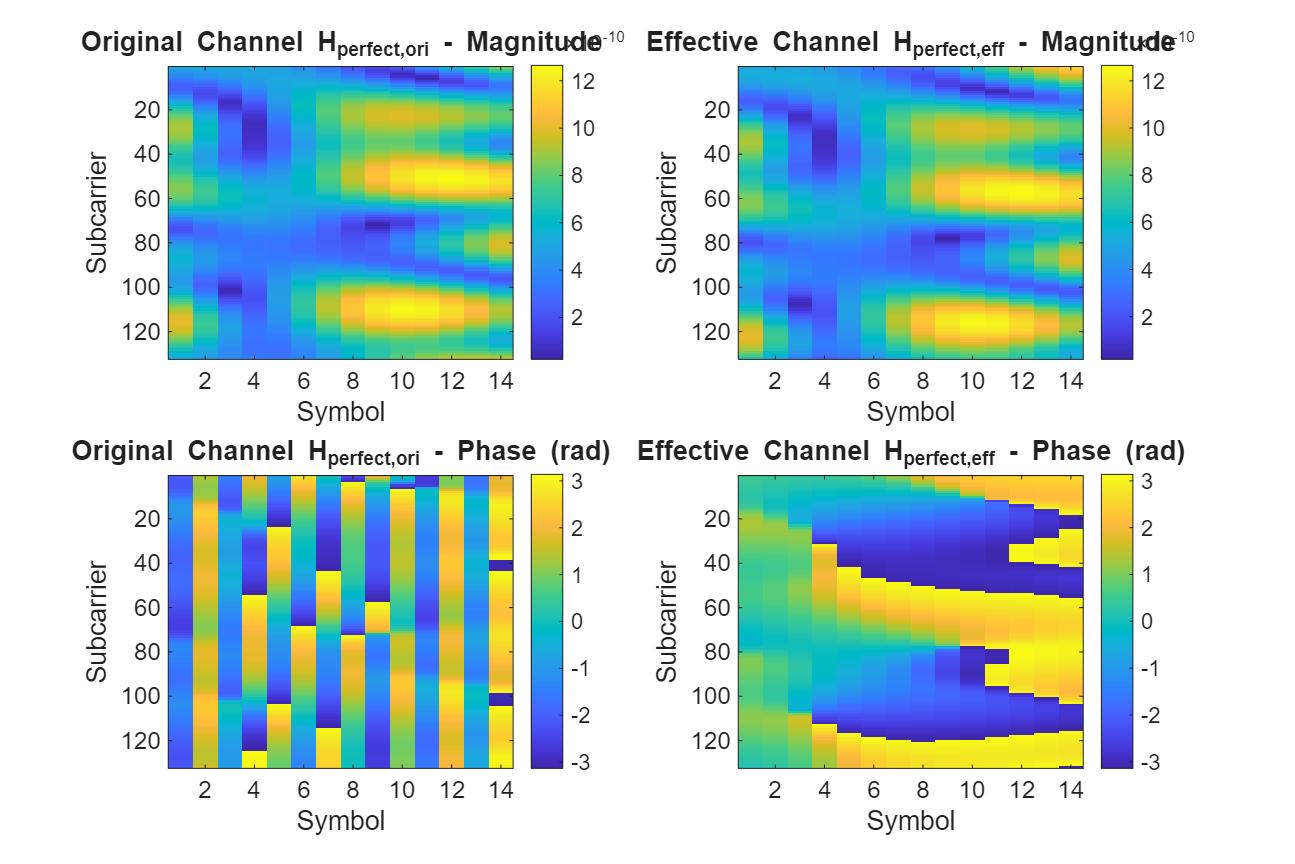


%% 6. Plotting Channel Grids (Original vs Effective Channel)
figure('Name', 'Channel Grids - Magnitude & Phase', 'Position', [200, 200, 1200, 800]);
subplot(2,2,1);
imagesc(abs(H_perfect_ori)); colorbar; set(gca, 'FontSize', 12);
title('Original Channel H_{perfect,ori} - Magnitude'); xlabel('Symbol'); ylabel('Subcarrier');

subplot(2,2,2);
imagesc(abs(H_perfect_eff)); colorbar; set(gca, 'FontSize', 12);
title('Effective Channel H_{perfect,eff} - Magnitude'); xlabel('Symbol'); ylabel('Subcarrier');

subplot(2,2,3);
imagesc(angle(H_perfect_ori)); colorbar; set(gca, 'FontSize', 12);
title('Original Channel H_{perfect,ori} - Phase (rad)'); xlabel('Symbol'); ylabel('Subcarrier');

subplot(2,2,4);
imagesc(angle(H_perfect_eff)); colorbar; set(gca, 'FontSize', 12);
title('Effective Channel H_{perfect,eff} - Phase (rad)'); xlabel('Symbol'); ylabel('Subcarrier');